Impedance control characterization based on $x_e(t)$, $\dot{x}_e(t)$ and $f(t)$, for a 2º Order model with sinusoidal input.

close all
clear 
clc
% A = position error (deviation) input amplitude
% w_u = position error input frequency (angular)
syms s t A w_u w_n zeta w_d
% Recording: K, D, M -> w_n = sqrt(K/M), zeta = D/(2*M*w_n)
% Matlab assumptions simplifies the computation and avoid complex numbers
assume([t A w_u w_n zeta], {'real','positive'})
assume(0 <= zeta <= 1) % I don't know if this works
Es = A * w_u/(s^2 + w_u^2);
Fs = (w_n^2 + 2*zeta*w_n*s + s^2)/(w_n^2)*Es

$$Fs = \frac{A\,w_{u}\,\left(s^{2}+2\,\zeta \,s\,w_{n}+{w_{n}}^{2}\right)}{{w_{n}}^{2}\,\left(s^{2}+{w_{u}}^{2}\right)}$$

Et = ilaplace(Es);
dEt = ilaplace(s*Es);
Ft = ilaplace(Fs);
f_expr = latex(simplify(Ft));

## Parametric curve (ellipse) {x_e, dx_e, f_ref} 

% to compute the gradient:
dFt = ilaplace(s*Fs);
assume(exp(-t*w_n*zeta) == 0) % from inspection on the original functions on t
Ft = simplify(Ft);
dFt = simplify(dFt);

Grad = [dEt, diff(dEt, t), dFt];   % Gradient Vect
Tang = [diff(dEt, t), diff(dEt, t, 2), diff(dFt, t)]; % Tangent  Vect
N = cross(Grad, Tang);                       % Normal Vector
N = simplify(N)

$$N = \left(\begin{array}{ccc} \frac{A^{2}\,{w_{u}}^{4}\,\left({w_{n}}^{2}-{w_{u}}^{2}\right)}{{w_{n}}^{2}} & \frac{2\,A^{2}\,{w_{u}}^{4}\,\zeta }{w_{n}} & -A^{2}\,{w_{u}}^{4} \end{array}\right)$$

Then, the normal vector can be simply defined as:

n_vec = [(w_n^2 - w_u^2) 2*zeta*w_n -w_n^2]

$$n\_vec = \left(\begin{array}{ccc} {w_{n}}^{2}-{w_{u}}^{2} & 2\,w_{n}\,\zeta & -{w_{n}}^{2} \end{array}\right)$$

n_expr = latex(N);
% Considering Tx, and Ty sequential rotations:
assume([t A w_u w_n zeta], {'real','positive'}), assume(zeta <= 1)
phi = asin(-n_vec(1)/norm(n_vec)); % minus due to right hand rule
tht = atan(-n_vec(2)/n_vec(3));
%syms phi tht real
Tx  = [1 0 0; 0 cos(tht) -sin(tht); 0 sin(tht) cos(tht)];
Ty  = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];

% express the ellipse projection without the 'Tz':
Projection = (Tx*Ty)' * [Et dEt Ft]';
% explicit the cos(t*w_u), and sin(t*w_u) coefficients:
Projection = simplify( collect(Projection, [cos(t*w_u) sin(t*w_u)]) );

% extract the Projection terms on the x and y axes only (1,2) as functions of cosine and
% sine
P(1,1) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [1 0]); % assuming sin = 1 and cos = 0 we get the sin coeff.
P(1,2) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [0 1]); % assuming sin = 0 and cos = 1 we get the cos coeff.
P(2,1) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [1 0]);
P(2,2) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [0 1]);
P = simplify(P/A); % A is just scaling the matrix and we can remove it to assume the cos/ sin functions with amplitude A
%Tz = [P [0 0]'; 0 0 1];

% Derive the root ellipse semiaxes:
N = abs(det(P));
M = P(1,1)^2 + P(2,1)^2 + P(1,2)^2 + P(2,2)^2;
N = simplify(N);
M = simplify(M);
a_x = simplify( 1/2*(sqrt(M + 2*N) + sqrt(M - 2*N)) );
b_x = simplify( 1/2*(sqrt(M + 2*N) - sqrt(M - 2*N)) );

## Plotting

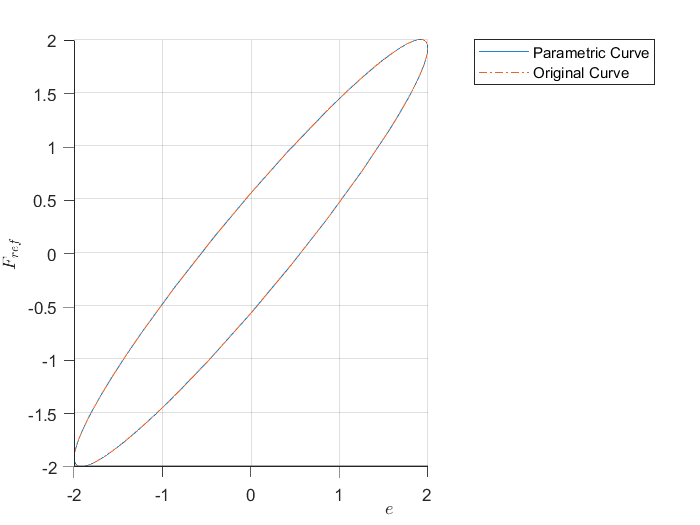

A0  = 2;
val_freq = 0.31831;      % => 2 rad/s
val_wu = 2*pi*val_freq;
Kd = 100; Dd = 2*sqrt(Kd); Md = 1;
val_k = Kd;
val_wn = sqrt(Kd/Md);
val_zt = 0.70; %Dd/(2*Md*val_wn);

T  = double( subs(Tx*Ty, [w_u w_n zeta],  [val_wu val_wn val_zt]));
Psbus = double( subs(P,[w_u w_n zeta],[val_wu val_wn val_zt]));
Tz = [Psbus [0 0]'; 0 0 1];

X = T*Tz*[A0*cos(val_wu*t), A0*sin(val_wu*t), 0]';
fplot3(X(1), X(2), X(3), [0 1/val_freq])
hold on
E  = subs(Et, [A w_u], [A0, val_wu]);
dE = subs(dEt, [A w_u], [A0, val_wu]);
F = subs(Ft, [A w_u w_n zeta], [A0 val_wu val_wn val_zt]);
fplot3(E, dE, F, [0 1/val_freq],'-.')
xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('Parametric Curve','Original Curve')
view([0.1 0.2])
hold off

% --- %

Inspecting how the curve changes according to $w_n$, $\zeta$:

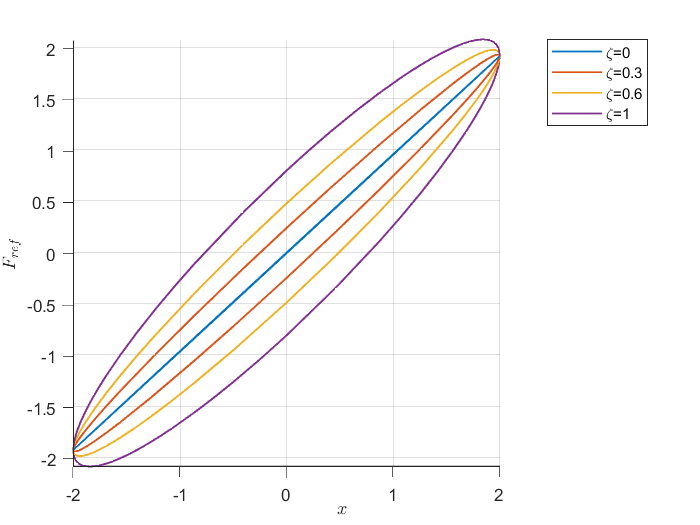

% Varying Zeta
zt_array = [0 0.3 0.6 1.0];
figure
for zt = zt_array
    val_wn = 10.0; % sqrt(Kd/Md);
    val_zt = zt;  % Dd/(2*Md*val_wn);
    values = [val_wu val_wn val_zt];
    
    T  = double( subs(Tx*Ty,  [w_u w_n zeta], values) );
    Psbus = double( subs(P, [w_u w_n zeta], values) );
    Tz = [Psbus [0 0]'; 0 0 1];
    
    % Parametric curve using the Transformations Tx*Ty*Tz
    X = T*Tz*[A0*cos(val_wu*t), A0*sin(val_wu*t), 0]'; %Tz contains a & b
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('\zeta= ', num2str(zt)))
    hold on
end

xlabel('$x$',"Interpreter","latex")
ylabel('$\dot{x}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('show')
view([0.1 0.2])
hold off

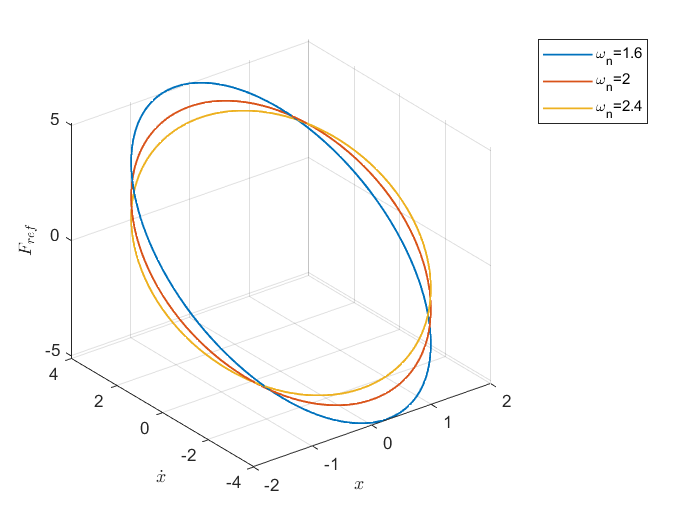

% Varying Omega (in a frequency wise perspective this might be useful to
% check how the ellipse change varying M, since w_n = sqrt(K/M)
array = [0.8*val_wu 1.0*val_wu 1.2*val_wu];
figure
for a = array
    val_wn = a; % sqrt(Kd/Md);
    val_zt = 1;  % Dd/(2*Md*val_wn);
    values = [val_wu val_wn val_zt];
    
    T  = double( subs(Tx*Ty,  [w_u w_n zeta], values) );
    Psbus = double( subs(P, [w_u w_n zeta], values) );
    Tz = [Psbus [0 0]'; 0 0 1];
    
    % Parametric curve using the Transformations Tx*Ty*Tz
    X = T*Tz*[A0*cos(val_wu*t), A0*sin(val_wu*t), 0]';
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('\omega_n= ', num2str(a)))
    hold on
end
xlabel('$x$',"Interpreter","latex")
ylabel('$\dot{x}$',"Interpreter","latex")
zlabel('$F_{ref}$',"Interpreter","latex")
legend('show')

%% Using M, D, K:
syms M D K
assume([M D K], {'real','positive'})
w_n = sqrt(K/M);
zeta = D/(2*M*w_n);
n_vec = [(w_n^2 - w_u^2) 2*zeta*w_n -w_n^2]

$$n\_vec = \left(\begin{array}{ccc} \frac{K}{M}-{w_{u}}^{2} & \frac{\text{D}}{M} & -\frac{K}{M} \end{array}\right)$$

n_vec = simplify([(w_n^2 - w_u^2) 2*zeta*w_n -w_n^2]*M)

$$n\_vec = \left(\begin{array}{ccc} K-M\,{w_{u}}^{2} & \text{D} & -K \end{array}\right)$$

phi = asin(-n_vec(1)/norm(n_vec)) % minus due to right hand rule

$$phi = -\mathrm{asin}\left(\frac{K-M\,{w_{u}}^{2}}{\sqrt{{\text{D}}^{2}+K^{2}+{\left|K-M\,{w_{u}}^{2}\right|}^{2}}}\right)$$

tht = atan(-n_vec(2)/n_vec(3))

$$tht = \mathrm{atan}\left(\frac{\text{D}}{K}\right)$$

Tx  = [1 0 0; 0 cos(tht) -sin(tht); 0 sin(tht) cos(tht)];
Ty  = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];

% express the ellipse projection without the 'Tz':
Projection = (Tx*Ty)' * [Et dEt Ft]';
% explicit the cos(t*w_u), and sin(t*w_u) coefficients:
Projection = simplify( collect(Projection, [cos(t*w_u) sin(t*w_u)]) );

% extract the Projection terms on the x and y axes only (1,2) as functions of cosine and
% sine
P(1,1) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [1 0]); % assuming sin = 1 and cos = 0 we get the sin coeff.
P(1,2) = subs(Projection(1,1), [cos(w_u*t) sin(w_u*t)], [0 1]); % assuming sin = 0 and cos = 1 we get the cos coeff.
P(2,1) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [1 0]);
P(2,2) = subs(Projection(2,1), [cos(w_u*t) sin(w_u*t)], [0 1]);
P = simplify(P/A); % A is just scaling the matrix and we can remove it to assume the cos/ sin functions with amplitude A
%Tz = [P [0 0]'; 0 0 1];

% Derive the root ellipse semiaxes:
N = abs(det(P));
M = P(1,1)^2 + P(2,1)^2 + P(1,2)^2 + P(2,2)^2;
N = simplify(N);
M = simplify(M);
a_x = simplify( 1/2*(sqrt(M + 2*N) + sqrt(M - 2*N)) );
b_x = simplify( 1/2*(sqrt(M + 2*N) - sqrt(M - 2*N)) );